clc
clear all
close all

%Import Data
%Baseline
Baseline= readmatrix('C:\Users\kondiboyina.v\Documents\Vineel\CalciumImaging_results\hydrostatic_Pressure\Bovine_cartilage_calbryte\DataAnalysis\CompiledData\DMSO_Baseline.txt');
%1Hz_0.2Mpa
Slow= readmatrix('C:\Users\kondiboyina.v\Documents\Vineel\CalciumImaging_results\hydrostatic_Pressure\Bovine_cartilage_calbryte\DataAnalysis\CompiledData\DMSO_1Hz_0p2.txt');
%1Hz_0.1Mpa
Fast= readmatrix('C:\Users\kondiboyina.v\Documents\Vineel\CalciumImaging_results\hydrostatic_Pressure\Bovine_cartilage_calbryte\DataAnalysis\CompiledData\DMSO_1Hz_0p1.txt');
%0.1Hz_0.2Mpa
p1= readmatrix('C:\Users\kondiboyina.v\Documents\Vineel\CalciumImaging_results\hydrostatic_Pressure\Bovine_cartilage_calbryte\DataAnalysis\CompiledData\DMSO_0p1Hz_0p2.txt');

%Putting together in a matrix
Data_n= [Baseline;Slow;Fast;p1]

Data_n = 	1.0e+04 *

    0.7572    0.0062    0.0012    0.0912    0.0260    0.0017    0.0001
    0.2548    0.0281    0.0013    0.0450    0.0066    0.0059    0.0001
    0.2012    0.0210    0.0015    0.0536    0.0304    0.0059    0.0001
    0.1637    0.0170    0.0016    0.0404    0.0226    0.0068    0.0001
    0.4486    0.0058    0.0014    0.0648    0.0254    0.0083    0.0001
    0.5904    0.0046    0.0012    0.0844    0.0175    0.0097    0.0001
    0.7287    0.0325    0.0010    0.0606    0.0178    0.0113    0.0001
    1.1197    0.0007    0.0012    0.0885    0.0415    0.0128    0.0001
    0.1977    0.0220    0.0027    0.0623    0.0210    0.0134    0.0001
    1.2988    0.0162    0.0011    0.0962    0.0146    0.0136    0.0001


a= length(Data_n)

a = 543

Data= nan(a,7); %making a matrix to store width of signaling
%Data_n= [Baseline;Slow;Fast;p1];


Signaling Width

Data(1:length(Baseline),1)= Baseline(:,3)*1.5;
Data(1:length(Slow),2)=Slow(:,3)*1.5;
Data(1:length(Fast),3)=Fast(:,3)*1.5;
Data(1:length(p1),4)=p1(:,3)*1.5;

%Average Width of Signaling
nanmean(Data)

ans =    28.3482   29.5807   36.2329   28.0539       NaN       NaN       NaN


nanstd(Data)

ans =    15.8616   17.9290   41.8575   18.0055       NaN       NaN       NaN



%vartestn(Data)
%remove outliers
Data= rmoutliers(Data);
Data= rmoutliers(Data);
Data= rmoutliers(Data);
Data= rmoutliers(Data);
Data= rmoutliers(Data);
Data= rmoutliers(Data);
nanmean(nanmean(Data))

ans = 19.1152

nanstd(nanmean(Data))

ans = 1.9137

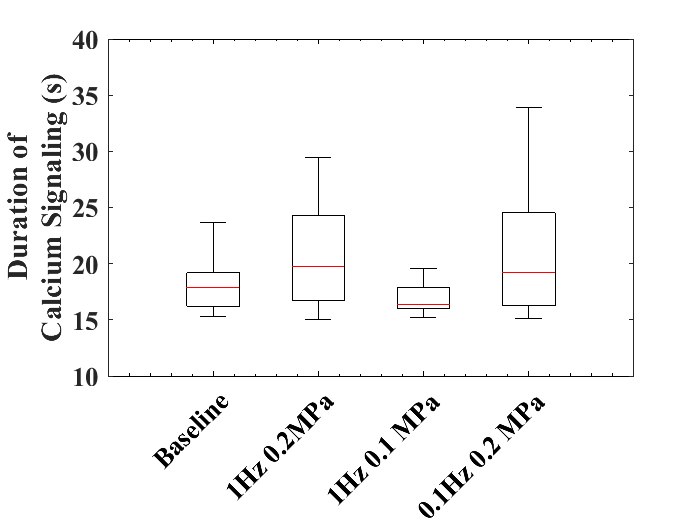


figure1=figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
boxplot(Data,'Colors','k','symbol', '')%,'Orientation',"horizontal")
xlim([0 5])
ylim([10 40])
ylabel({"Duration of"; "Calcium Signaling (s)"})
xticks([1 2 3 4])
xticklabels({'Baseline','1Hz 0.2MPa','1Hz 0.1 MPa','0.1Hz 0.2 MPa'})
xtickangle(45)
h=findobj('LineStyle','--'); set(h, 'LineStyle','-');
lines = findobj(gcf, 'type', 'line', 'Tag', 'Median');
set(lines, 'Color', 'r');
% Create xlabel
%xlabel('Loading Conditions','FontWeight','bold','FontName','Times New Roman','FontSize',12);
box(axes1,'on');
set(axes1,'ClippingStyle','rectangle','FontName','Times New Roman',...
    'FontSize',16,'FontWeight','bold','XColor',[0 0 0],'XTick',[1 2 3 4],...
    'XTickLabel',{'Baseline','1Hz 0.2MPa','1Hz 0.1 MPa','0.1Hz 0.2 MPa'},'XColor',[0 0 0],'XMinorTick',...
    'on','ZColor',[0 0 0]);
% Change the renderer to "Painters"
set(gcf, 'Renderer', 'Painters')

% Save the plot as a PNG image
%clc
print('Width.png','-dpng', '-r300')

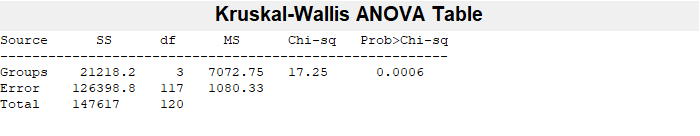

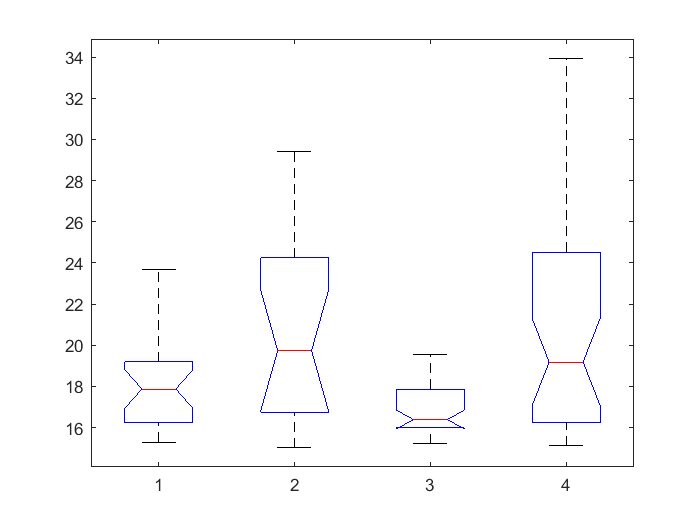

%aov= anova1(Data);

[p,tbl,stats] = kruskalwallis(Data);

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


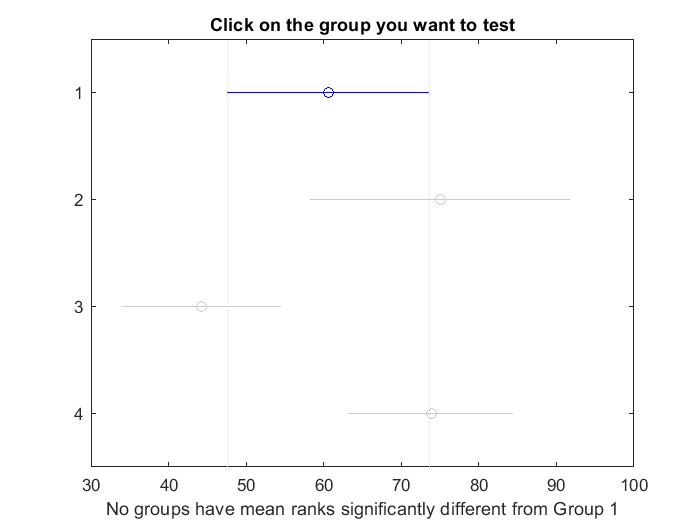

[c1,m,h,gnames] = multcompare(stats,"CType","bonferroni"); %pvalues, means and SE, figurehandles, groupnames